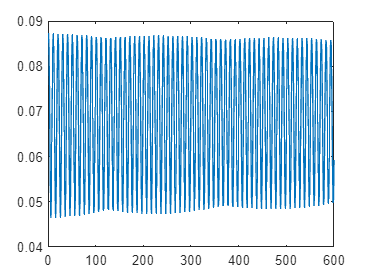

% Define the parameters
clc
clear

T = 40;
t =0;
dt=0.05;

X =[0; 0; 15; deg2rad(5); deg2rad(5); 0.5; 0.5; 0; 0;1];
Xshow=zeros(10,T/dt);

t_1         = linspace(0, 100, 600);
y0        = [0; 0; 15; deg2rad(5); deg2rad(5); 0.5; 0.5; 0; 0; 1];
[tsim, y] = ode45(@nonLinearSys, t_1, y0);
xsim      = y(:,4); 

save('Ploting/testeNonLinearDataV2.mat', "y");
 
plot(xsim)

function [DX] = nonLinearSys(t,X)

d2X = zeros(5,1);
 
Ma = 13297+3877.79-246.6871; 
Mp = 31629+0.6895; 
g = 9.81; %made this negative
rho_air = 1.23;
l = 8; %If change, also change in animation
Va= 39477.88;

x = X(1);
y = X(2);
z = X(3);
alpha =X(4);
beta=X(5);
dx =X(6);
dy =X(7);
dz =X(8);
dalpha=X(9);
dbeta =X(10);


M = [1 0 0 0 0 0 0 0 0 0;
     0 1 0 0 0 0 0 0 0 0;
     0 0 1 0 0 0 0 0 0 0;
     0 0 0 1 0 0 0 0 0 0;
     0 0 0 0 1 0 0 0 0 0;
     0 0 0 0 0 (Ma+Mp) 0 0 Mp*l*cos(alpha)*cos(beta) -Mp*l*sin(alpha)*sin(beta);
   0 0 0 0 0 0 (Ma+Mp) 0 Mp*l*cos(alpha)*sin(beta) Mp*l*cos(beta)*sin(alpha);
   0 0 0 0 0 0 0 (Ma+Mp) Mp*l*sin(alpha) 0;
   0 0 0 0 0 Mp*l*cos(alpha)*cos(beta) Mp*l*cos(alpha)*sin(beta) Mp*l*sin(alpha) Mp*l^2 0;
   0 0 0 0 0 Mp*l*sin(alpha)*-sin(beta) Mp*l*sin(alpha)*cos(beta) 0 0 Mp*l*l*sin(alpha)*sin(alpha)];


A = [dx;
    dy;
    dz;
    dalpha;
    dbeta;
    Mp*l*dalpha*dalpha*cos(beta)*sin(alpha)+Mp*l*dbeta*dbeta*cos(beta)*sin(alpha)+Mp*2*l*dalpha*dbeta*cos(alpha)*sin(beta);
    Mp*l*dalpha*dalpha*sin(beta)*sin(alpha)+Mp*l*dbeta*dbeta*sin(beta)*sin(alpha)-Mp*2*l*dalpha*dbeta*cos(alpha)*cos(beta);
    -Mp*l*dalpha*dalpha*cos(alpha)-g*(Ma+Mp)+Va*rho_air*g; %switched sign in the g terms
    -Mp*g*l*sin(alpha)+Mp*l*l*dbeta*dbeta*cos(alpha)*sin(alpha);
   -Mp*l*sin(alpha)*2*l*dbeta*dalpha*cos(alpha)];

d2X = M \ A;

DX =[d2X];

end



